# What drives the changes in the FSTD?

%% Read in the data.
clear
close all
addpath functions
addpath packages/quiverwcolorbar
clc
% Parameters
sector = "SA";
grid = 'gx1';
case_name = 'ocnatmo';
filedir = '/Volumes/NoahDay5TB/cases/ocnatmo/history/iceh.';
%'cases/momentum/history/iceh.'; %'/Volumes/NoahDay5TB/cases/momentum/history/iceh.2009-09-30.nc';
[lat,lon,row] = grid_read(grid);
user = "a1724548";
% Make sector mask
%[len,wid] = size(lat);
fig_count = 0;


coords = sector_coords(sector);
% Take the location to be the centre of the sector
sector = "SA";%struct('coords',sector_coords(sector),'centre_lon',(coords(1,1)+coords(2,1))/2,'north_lat',[],'south_lat',[]);
clear coords

initial_date.day = 3;
initial_date.month = 7;
initial_date.year = 2005; % 2005 is a spin-up year
initial_date.char = sprintf('%d-0%d-0%d', initial_date.year, initial_date.month, initial_date.day);

filename = strcat(filedir,initial_date.char,'.nc');

pram.max_wind = 10; % m/s
pram.min_wind = 5; % m/s
pram.min_SIC = 0.15; % m/s
pram.total_datapoints = 1;
pram.quiver_color = 'red';
pram.label_color = 0.7*[0.4660 0.6740 0.1880];
pram.ice_edge_color = 0.7*[0.4660 0.6740 0.1880];
pram.colormap = 'ice';


aice_data = data_format_sector(filename,"aice",sector);
idx = aice_data < eps;
aice_data(idx) = NaN;
lat_vec = reshape(lat,1,[]);
lon_vec = reshape(lon,1,[]);

SIC = 0.15;
[lat_ice_edge, lon_ice_edge] = find_ice_edge(aice_data,SIC,sector,lat,lon);

## 1. Advection

### Variables:

- d

## 2. Thermodynamics

### Variables:

- dafsd_latg

- dafsd_latm

- dafsd_weld

- dafsd_newi

### Dafsd_latg

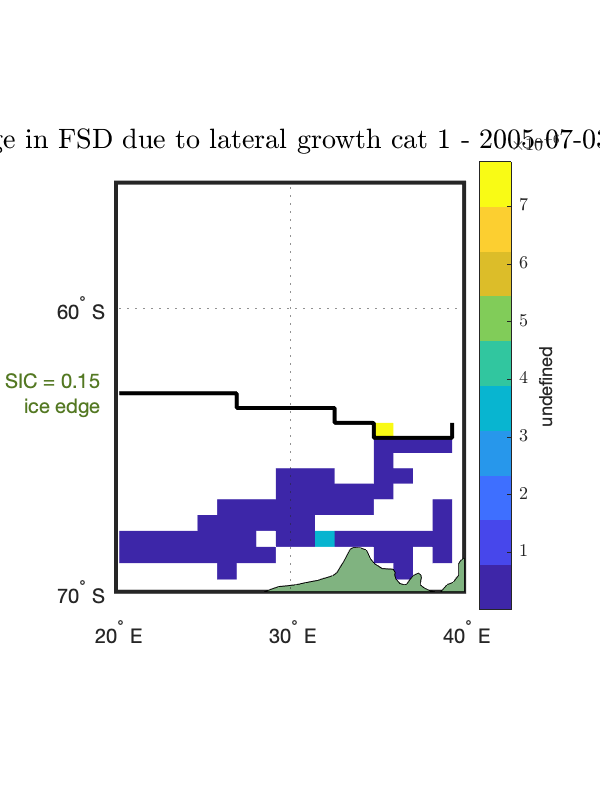

dafsd_latg_data = data_format_sector(filename,"dafsd_latg",sector,3);
dafsd_latg_data_1 = dafsd_latg_data(:,:,1);
idx = dafsd_latg_data_1 < eps;
dafsd_latg_data_1(idx) = NaN;
fig_count = fig_count + 1;
figure(fig_count)
fig.all = map_plot(dafsd_latg_data_1,"dafsd_latg",sector);  
    plotm(lat_ice_edge,lon_ice_edge,'-','color','k','LineWidth',2)
    t = textm(lat_ice_edge(20),lon_ice_edge(18),sprintf('SIC = %g\n ice edge',pram.min_SIC),'HorizontalAlignment','right');
    t.Color = pram.label_color;
    set(gcf,'Position',[1200 1000 300 400])
    title(strcat("Change in FSD due to lateral growth cat 1 - ",initial_date.char), 'interpreter','latex','FontSize', 14)
    colormap(parula(10))

### Dafsd_latm

### Dafsd_weld

### Dafsd_newi

## 3. Mechanical redistribution

## 4. Wave-induced ice fracture

### Variables:

- dafsd_wave

### Dafsd_wave

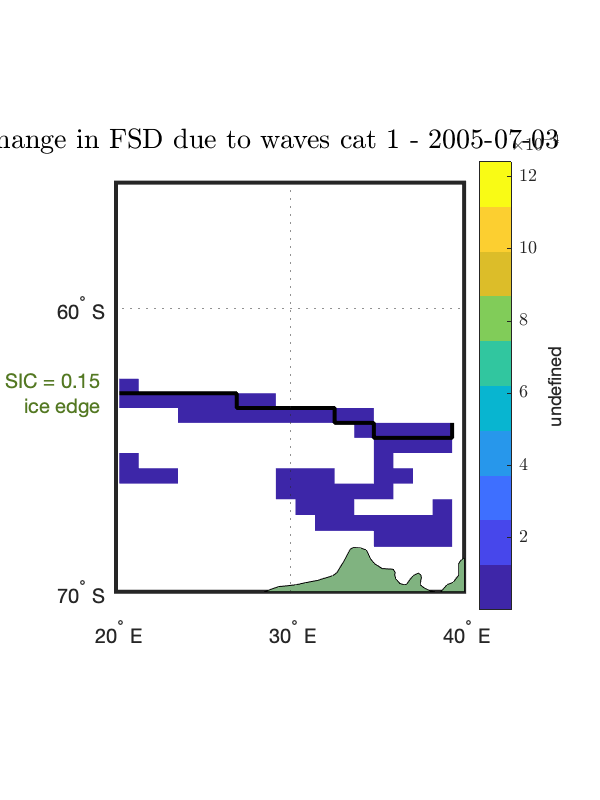

dafsd_latg_data = data_format_sector(filename,"dafsd_wave",sector,3);
dafsd_latg_data_1 = dafsd_latg_data(:,:,1);
idx = dafsd_latg_data_1 < eps;
dafsd_latg_data_1(idx) = NaN;
fig_count = fig_count + 1;
figure(fig_count)
fig.all = map_plot(dafsd_latg_data_1,"dafsd_latg",sector);  
    plotm(lat_ice_edge,lon_ice_edge,'-','color','k','LineWidth',2)
    t = textm(lat_ice_edge(20),lon_ice_edge(18),sprintf('SIC = %g\n ice edge',pram.min_SIC),'HorizontalAlignment','right');
    t.Color = pram.label_color;
    set(gcf,'Position',[1200 1000 300 400])
    title(strcat("Change in FSD due to waves cat 1 - ",initial_date.char), 'interpreter','latex','FontSize', 14)
    colormap(parula(10))